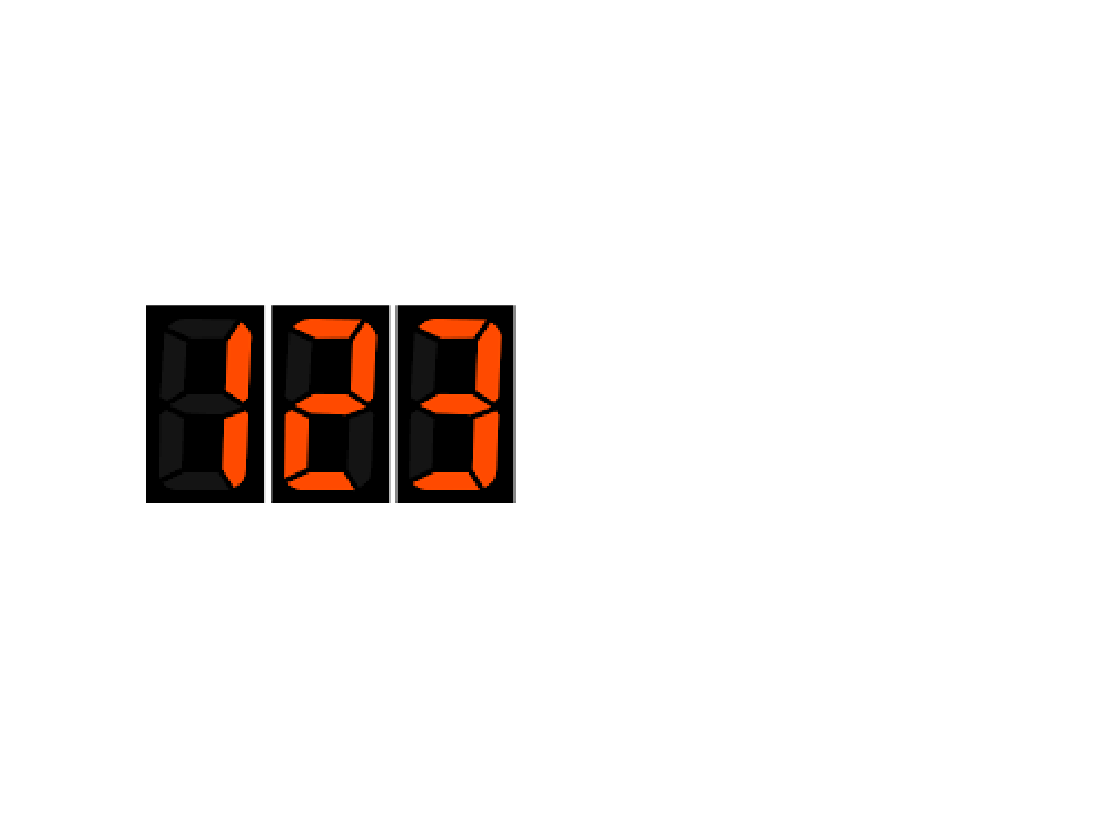

% Load image
[A,c] = imread('numbers.png');
A = A(1:90, 1:168);
subplot(1,2,1), imshow(A,c)

[n,m] = size(A);
NM = n*m;

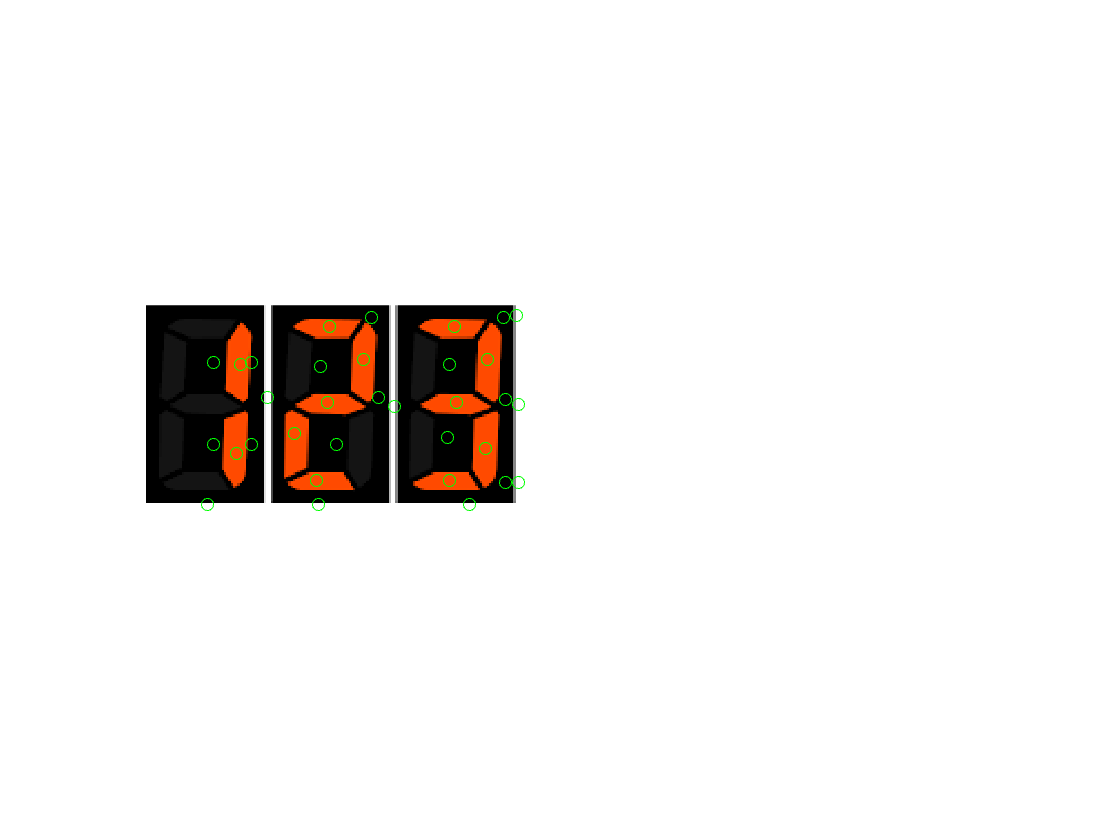

% Define labels
L = [1, 2, 3]; % 1 - white, 2 - black, 3 - red
% Define seeds
S = [42, 55, 1; 46, 112, 1; 90, 78, 1; 90, 28, 1; 90, 146, 1; 45, 168, 1; 5, 167, 1; 80, 168, 1;
26, 31, 2; 63, 31, 2; 26, 48, 2; 63, 48, 2; 63, 86, 2; 28, 79, 2; 6, 102, 2; 27, 137, 2; 60, 136, 2; 6, 161, 2; 80, 162, 2; 42, 105, 2; 43, 162, 2
27, 43, 3; 67, 41, 3; 79, 77, 3; 58, 67, 3; 44, 82, 3; 25, 98, 3; 10, 83, 3; 79, 137, 3; 65, 153, 3; 44, 140, 3; 25, 154, 3; 10, 139, 3];
hold on
plot(S(:,2), S(:,1), 'o', 'Color', 'green')
hold off

T = 5000; % Number of steps
img = zeros(n,m,3);
for p = 1:3
    for i = 1:n
        for j = 1:m
            img(i,j,p) = c(A(i,j)+1,p);
        end
    end
end

tic
W = sparse(calculate_weights(img,150));
toc

Elapsed time is 1.250047 seconds.


tic
H = construct_hamiltonian(W, 0.001);
toc

Elapsed time is 1.786570 seconds.


tic
for i = 1:numel(L) % use parfor if available
    sprintf("Working with label: %d", i)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(numel(A),1);
    for p = 1:subset_length
        if subset(p,2) + m*(subset(p,1)-1) > numel(A)
            p
            subset(p,2) + m*(subset(p,1)-1)
        end
        A_sub( subset(p,2) + m*(subset(p,1)-1) ) = 1;
    end
    state = 1/sqrt(subset_length) * sparse(A_sub);
    sprintf("The norm of our intial state vector is: %d", dot(full(state), full(state)))
    state = update_state(-T*1i, H, state);
    D(:,i) = retrieve_position(state);
    % sprintf("After %d steps, the norm is: %d", T, dot(full(state), full(state)))
    % LD(:,i) = 1/T * sum(D,2);
    % sprintf("Limiting distribution of label %d found", i)
end

ans = "Working with label: 1"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "Working with label: 2"

ans = "The norm of our intial state vector is: 1"

ans = "Working with label: 3"

ans = "The norm of our intial state vector is: 1.000000e+00"

toc

Elapsed time is 3.991710 seconds.


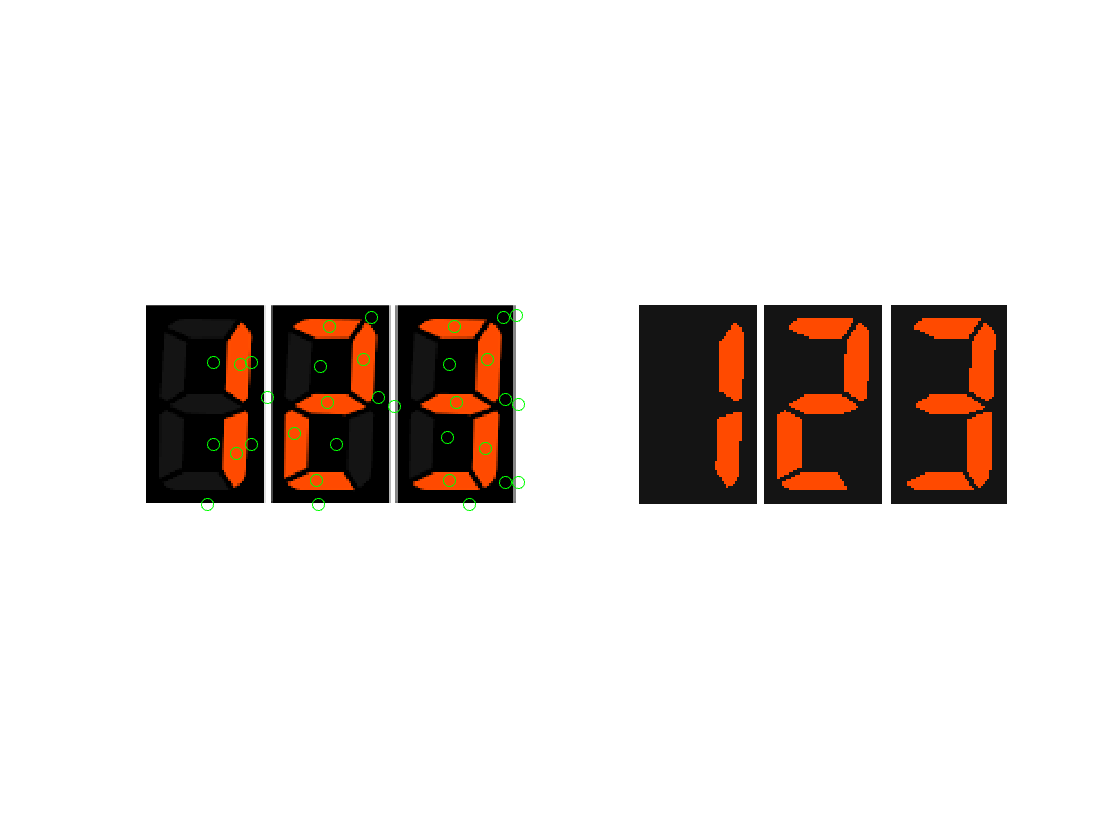

B_os = zeros(n,m);
b = [4,3,2];
for i = 1:n
    for j = 1:m
        k = find_seed(D,i,j,m);
        B_os(i,j) = k;
    end
end

subplot(1,2,2), imshow(B_os,c(b,:))